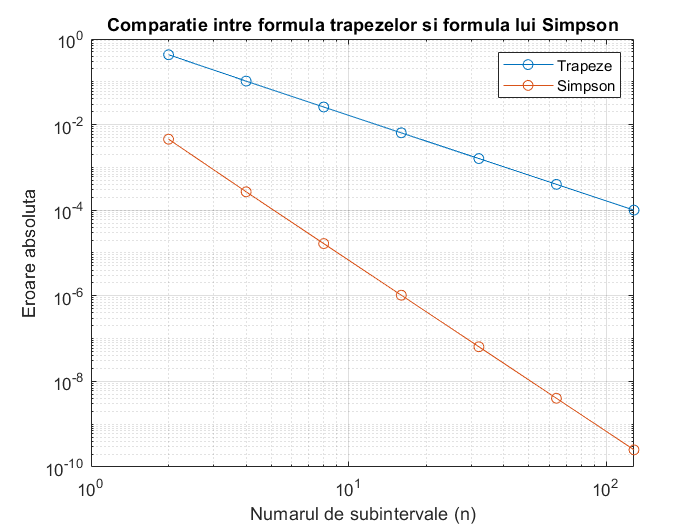

% definirea functiei si a limitelor intergralei
f = @(x) sin(x);
a = 0;
b = pi;

% valoarea integralei calculata de MatLab
I_real = integral(f, a, b);

% definirea numarului de subintervale pentru aproximatie
n_values = [2, 4, 8, 16, 32, 64, 128];

% calculul aproximatiilor cu formula trapezelor si Simpson
I_trapezoidal = zeros(size(n_values));
I_simpson = zeros(size(n_values));

for i = 1:length(n_values)
    I_trapezoidal(i) = trapezes(f, a, b, n_values(i));
    I_simpson(i) = Simpson(f, a, b, n_values(i));
end

% plotare rezultate
figure;
loglog(n_values, abs(I_trapezoidal - I_real), '-o', 'DisplayName', 'Trapeze');
hold on;
loglog(n_values, abs(I_simpson - I_real), '-o', 'DisplayName', 'Simpson');
xlabel('Numarul de subintervale (n)');
ylabel('Eroare absoluta');
title('Comparatie intre formula trapezelor si formula lui Simpson');
legend('show');
grid on;